# Further Exploration 2: Use Deep Learning for Time Series Forecasting

Deep learning is a specialized form of machine learning. An essential step in the traditional machine learning workflow is to engineer and extract relevant features from the raw data. In deep learning, a [*neural network*](https://www.mathworks.com/discovery/neural-network.html) automatically extracts the features for you. Training such complex models requires a large amount of labeled input data, along with significant computational power.

The *network architecture* dictates the network's behavior and purpose. The specific arrangement of layers of fundamental units (or neurons), the behavior of these units in each layer, and the connections between them characterize the network architecture. 

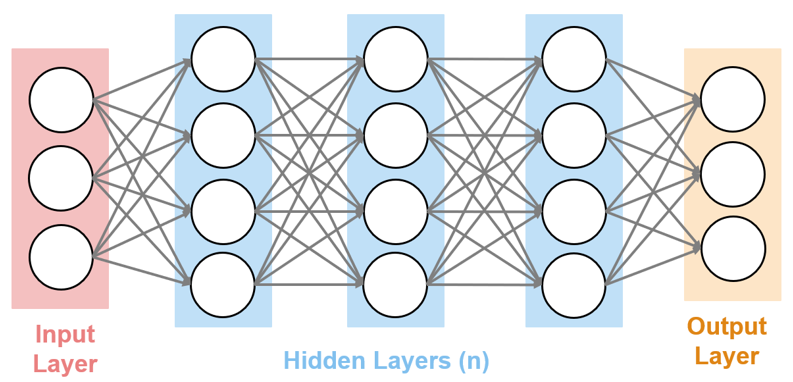

Two commonly used deep neural network types are the Convolutional Neural Network (CNN) and the Recurrent Neural Network (RNN). The CNN architectures are modeled to behave like the human visual cortex and are particularly good at processing images. RNNs are a type of network that have connections feeding back into the previous layers (or the same layer) in addition to the typical feed-forward connections. These are particularly good at processing sequences such as text, speech, and other time series.

### Long Short-Term Memory (LSTM)

For electricity load forecasting, we use the Long Short-Term Memory (LSTM) architecture for an RNN. A key distinguishing element of an LSTM architecture is a memory cell (in place of the traditional neuron) as its fundamental unit. These cells contain three gates (input, forget, and output) that control how the information flows through the cell. The weights of the cell control each gate. The training algorithm tries to optimize these weights based on the network's output error. Learn more about LSTMs [here](https://www.mathworks.com/discovery/lstm.html).

** Note that a deep neural network takes a long time to train. It is recommended to have access to a GPU.**

- Study this example to get started: [Time Series Forecasting Using Deep Learning](https://www.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html)

- Follow a similar workflow for electricity load forecasting. 

- Start by loading the data from `nyiso_cleaned.mat`. Do not retime the data.

- Preprocess the data by standardizing the load values; subtracting the mean and then dividing by the standard deviation. 

- Organize the input and output load variables such that the network will learn to predict the load one day (24 hours) in advance. In other words, for an input at the current time, the output should be the electrical load 24 hours into the future.

- Train the same LSTM architecture as used in the example linked above.

- Evaluate the performance of the model.

- Try using the different training options.

## **Sample starter solution **

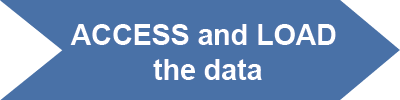

% Load the electricity load data.
load nyiso_cleaned.mat nyiso;
head(nyiso)

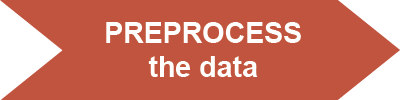

% Extract the data for New York City.
NYCData = nyiso(:,"N_Y_C_");

% Convert timetable to a table
NYCData = timetable2table(NYCData);

% Change the table column name to be more general.
NYCData.Properties.VariableNames(2) = "Load"

% Split the date into training and test sets.
TrainStart = "2017-May-08 00:00";
TrainEnd = "2019-Dec-31 23:00";
idxtrain = isbetween(NYCData.Date, datetime(TrainStart,"TimeZone","America/New_York"), ...
                                     datetime(TrainEnd,"TimeZone","America/New_York")); 
idxtest = NYCData.Date > datetime(TrainEnd,"TimeZone","America/New_York");
TrainNYC = NYCData(idxtrain,2:end)
TestNYC = NYCData(idxtest,2:end)

% Standardize the data by subtracting the mean and dividing by standard
% deviation. Remember that, during training, the model should not be exposed to any aspect of the test data. 
% Only use the mean and standard deviation of the training data. 
mu = mean(TrainNYC.Load);
sig = std(TrainNYC.Load);
StandardLoad = (TrainNYC.Load - mu)/sig;

% Append the standardized data to the table
TrainNYC.StandardLoad = StandardLoad

% Similary for testing, use the same mean, mu and standard deviation, sig
% to standardize. These parameters are a part of the trained model in a way.
% Test data parameters should not be used to prepare the data.
mu = mean(TestNYC.Load);
sig = std(TestNYC.Load);
StandardLoad = (TestNYC.Load - mu)/sig;
TestNYC.StandardLoad = StandardLoad

% To predict one day in advance, we want to set the data so that the ouput
% for each time step is the load value 24 hours in the future. To do this,
% create a shifted version of the load series by one day.

            
$$\frac{\textrm{intervals}}{\textrm{day}}=\;\frac{\textrm{hours}}{\textrm{day}}*\frac{\textrm{minutes}}{\textrm{hour}}*\frac{\textrm{intervals}}{\textrm{minutes}}$$


% Compute the number of time steps to shift.
NumIntervals = 288;

% Shift the load values by the number of intervals to create the input (X)
% and output (y) variables.
XTrain = TrainNYC.StandardLoad(1:end-NumIntervals)';
yTrain = TrainNYC.StandardLoad(NumIntervals+1:end)';
XTest = TestNYC.StandardLoad(1:end-NumIntervals)';
yTest = TestNYC.StandardLoad(NumIntervals+1:end)';

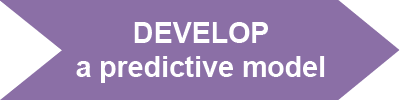

% Create the network architechture with a sequence input, an lstm layer, a
% fully connected layer, and a regression output.
NumFeatures = 1;
NumResponses = 1;
NumHiddenUnits = 200;

layers = [ ...
    sequenceInputLayer(NumFeatures)
    lstmLayer(NumHiddenUnits)
    fullyConnectedLayer(NumResponses)
    regressionLayer]

% Analyze the network architecture.
analyzeNetwork(layers)

Find more information about the different training options [here](https://uk.mathworks.com/help/deeplearning/ref/trainingoptions.html). The various training options define the [hyperparameters](https://www.mathworks.com/videos/applied-machine-learning-part-3-hyperparameter-optimization-1547849445386.html) of the model. Adjusting and tuning them helps to optmize the model. 

% Set the training options. Make sure you display the training progress to monitor the progress and identify any hyperparameters that need to be tuned.
options = trainingOptions("adam", ...
    "MaxEpochs",20, ...
    "GradientThreshold",1, ...
    "InitialLearnRate",0.01, ...
    "Verbose",0, ...
    "Plots","training-progress");

** Note that a deep neural network can take several hours to train on a CPU. For a significantly improved training time, it is preferable to use a GPU if available. For more information, see **[**this**](https://www.mathworks.com/help/releases/R2021a/deeplearning/ref/trainingoptions.html#d123e115332)** documentation section. **

% Train the network.
net = trainNetwork(XTrain,yTrain,layers,options)

% Test the trained network model.
yPred=predict(net,XTest);

% De-standardize the resulting outputs by multiplying with standard
% deviation and adding back the mean.
yPredTrue = sig*yPred + mu;

% Get the actual load values for test data to compare with predictions.
yTestTrue = TestNYC.Load(NumIntervals+1:end)';

% Measure the performance with RMSE.
rmse = sqrt(mean((yPredTrue-yTestTrue).^2))

% Plot the results.
% Get the test dates from original data.
TestDates = table2timetable(NYCData(idxtest,:));
TestDatesPred = TestDates(NumIntervals+1:end,1);

% Construct a table containing the variables to plot.
PlotData = TestDatesPred;
PlotData.ObsTest = yTestTrue';
PlotData.PredTest = yPredTrue';
PlotData.Error = (yPredTrue - yTestTrue)';
PlotVars = {["ObsTest","PredTest"],"Error"};
figure
stackedplot(PlotData,PlotVars, ...
    "Title", ["Comparison of actual and predicted load"; "Test RMSE= " + num2str(rmse)]);

 **Reflect**

How was this process different from the machine learning workflow covered in the earlier parts of this module? Consider these factors: the amount of data, domain knowledge needed, your level of understanding of deep learning networks versus traditional models, computational time, computational power, and accuracy of the forecast.